%Reading the csv file to extract data
data = readtable('SENSEX_DATA.csv');

%Converted table type to array type, and then creating a row vector of the
%Open column in Data table
fullopeningdata = data(:,2);
fullopeningdata = table2array(fullopeningdata);
fullopeningdata = fullopeningdata';
n = length(fullopeningdata);
disp(n);

        2560




%Extracting only the values for Financial Year 2016 and 2017
openingdata = fullopeningdata(1493:1987);
n1 = length(openingdata);

% Converted table type to array type, and then creating a row vector of the
% Close cloumn of Data table
closingdata=data(:,5);
closingdata=table2array(closingdata);
closingdata=closingdata';

% ANALYSIS FOR OPENING DATA ONLY. A SIMILAR ANALYSIS CAN BE DONE FOR CLOSING
% DATA AS WELL.

% NOW MAKING IT A STATIONARY TIME SERIES.
o_mean=mean(openingdata);
disp(o_mean);

   2.8683e+04



o_var=var(openingdata);
disp(o_var);

   8.1369e+06



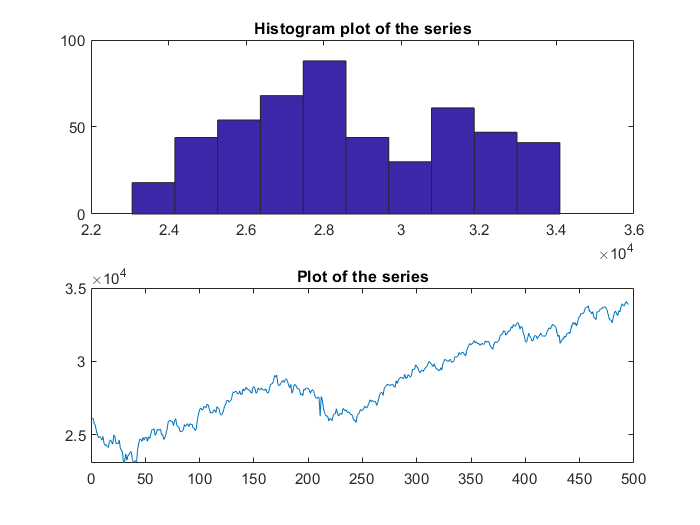


% PLOTTING THE HISTOGRAM AND THE TIME SERIES DATA
figure
subplot(2,1,1);
hist(openingdata);
title("Histogram plot of the series");
subplot(2,1,2);
plot(openingdata);
title("Plot of the series");

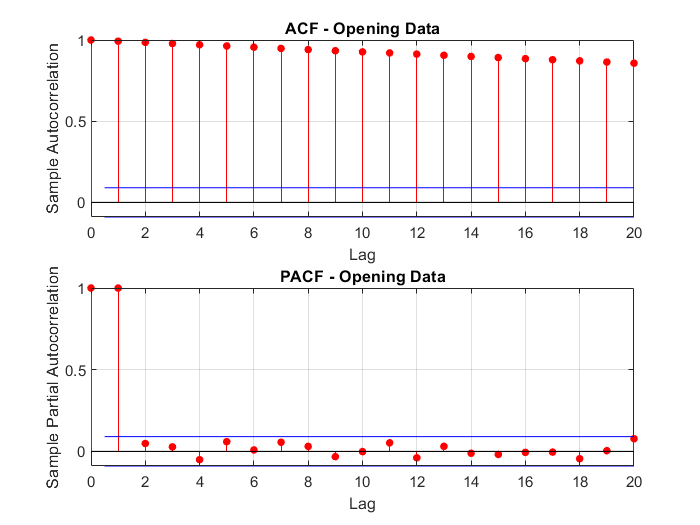


% PLOTTING THE ACF(Auto Correlation Function) and PACF(Partial Auto
% Correlation Function) PLOTS OF THE EXTRACTED TIME SERIES
figure
subplot(2,1,1);
autocorr(openingdata);
title("ACF - Opening Data");
subplot(2,1,2);
parcorr(openingdata);
title("PACF - Opening Data");

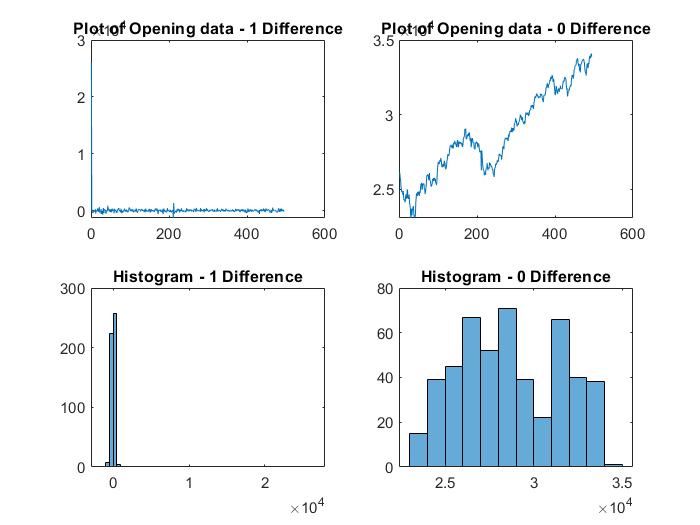


% DIFFERENCING THE DATA TO CHECK IF IT BECOMES STATIONARY OR NOT AS A
% GENERAL APPROACH
open1(1)= openingdata(1);
for i=2:n1
    open1(i)=openingdata(i) - openingdata(i-1);
end

%Plotting the DIFFERENCED MODEL vs ORIGINAL MODEL
figure
subplot(2,2,1)
plot(open1);
title("Plot of Opening data - 1 Difference");
subplot(2,2,2)
plot(openingdata);
title("Plot of Opening data - 0 Difference");
subplot(2,2,3)
histogram(open1);
title("Histogram - 1 Difference");
subplot(2,2,4)
histogram(openingdata);
title("Histogram - 0 Difference");

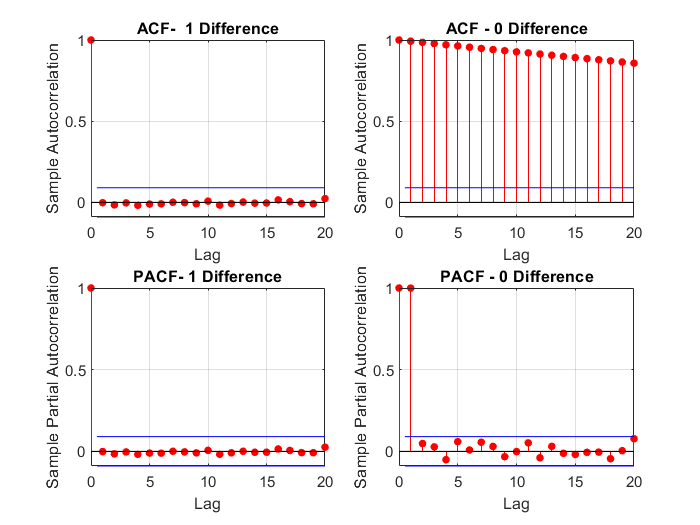


%Comparing their ACF, PACF plots
figure
subplot(2,2,1)
autocorr(open1);
title("ACF-  1 Difference");
subplot(2,2,2)
autocorr(openingdata);
title("ACF - 0 Difference");
subplot(2,2,3)
parcorr(open1);
title("PACF- 1 Difference");
subplot(2,2,4)
parcorr(openingdata);
title("PACF - 0 Difference");


% Dickey-Fuller Test or the Augmented Dickey-Fuller Test.
% What does it do: Checks whether a time series is stationary or not
% We will be testing it against our data obtained.


%NOTE THAT h value is 0 meaning non stationary for above. MEaning that p
%value is greater than 0.05. 5 percent criticality
[h,p]=adftest(openingdata);
disp("ADF TEST RESULT FOR 0 DIFFERENCING:");

ADF TEST RESULT FOR 0 DIFFERENCING:


disp([h,p]);

         0    0.9698





%NOTE THAT h value is 1, meaning a stationary time series (Or your p value
%is less than 0.05, 5 percent criticality
[h1,p1]=adftest(open1);
disp("ADF TEST RESULT FOR 1 DIFFERENCING:");

ADF TEST RESULT FOR 1 DIFFERENCING:


disp([h1,p1]);

    1.0000    0.0010





%ARIMA MODELLING

ARIMA_Theo= arima(0,1,0); %Theoretical ARIMA model
[ARIMA_Theo1,~,LogLikelihood]= estimate(ARIMA_Theo, openingdata');

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                Value     StandardError    TStatistic      PValue   
                ______    _____________    __________    ___________

    Constant    15.638       10.111          1.5466          0.12195
    Variance     50402       1750.6          28.792      2.6907e-182



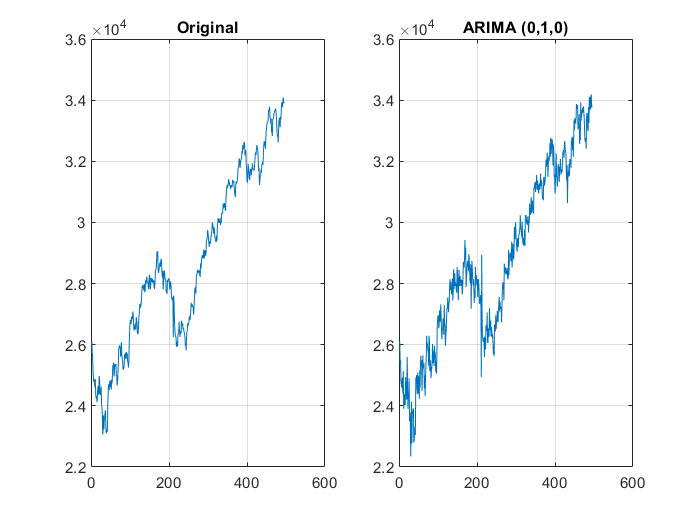


rng(1);                 %To maintain the reproducibility since the ramndom values generated depends on the seed,
                        % by fixing the seed would preserve the generation of those random number

residual= infer(ARIMA_Theo1, openingdata');     % This line basically generate the difference in the 
                                                % values b/w the actual and
                                                % fitted model.
                                             
prediction= openingdata +residual';             % Here we are basically extracting the fitted model values

%PLOT OF THE ORIGINAL AND THE FITTED MODEL
figure
subplot(1,2,1);
plot(openingdata);
title("Original");
grid on
subplot(1,2,2);
plot(prediction);
title("ARIMA (0,1,0)");
%legend('Original','ARIMA(0,1,0)','Location','best');
grid on

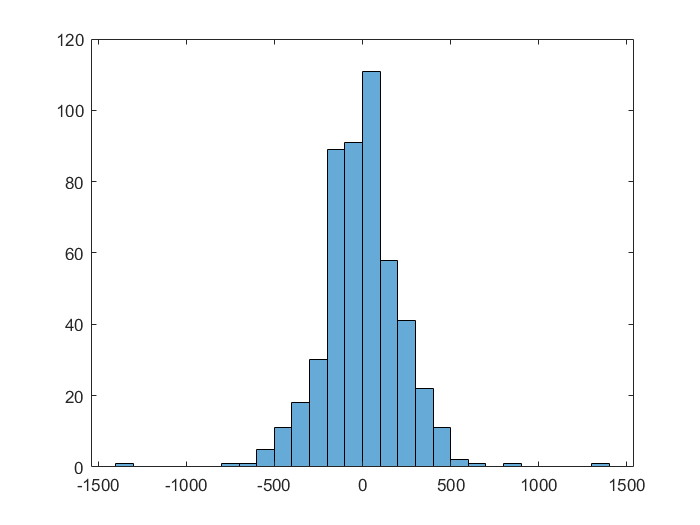


figure
histogram(residual);

% So since we have predicted the model, let's findout how accurate is our
% estimation.

% So how do we find how accurate our model is?
% We can go for the aic(AkaikeAkaike's Information Criteria) and bic(Bayesian Information Criteria) values.
% In short, aic tell whether the model will over fit the actual time series and 
% bic tell whether the model will under fit the actual time series . So, lesser is the aic and bic value the better is
% the predicted value.
[aic,bic]= aicbic(LogLikelihood,2,495);


% Finding the best fit model in the practical sense by comparing with other models if there are any
% model which is better than our present theortical model.

Model_table = "arima(0,1,0)";
aic_table = aic;
bic_table = bic;

m=2;
for i = 1:2
    for j = 1:2
        for k=1:2
            arima_model(m-1) = arima(i,j,k);
            [~,~,LoglikehoodE] = estimate(arima_model(m-1),openingdata','display','off');
            [aic_inter,bic_inter] = aicbic(LoglikehoodE,2,250);
            Model_table(m) = ['arima(',num2str(i),',',num2str(j),',',num2str(k),')'];
            aic_table(m) = aic_inter;
            bic_table(m) = bic_inter;
            m=m+1;
        end
    end
end


Comparision = table(Model_table',aic_table',bic_table');
disp(Comparision);

         Var1          Var2      Var3 
    ______________    ______    ______

    "arima(0,1,0)"    6766.5    6774.9
    "arima(1,1,1)"    6764.6    6771.6
    "arima(1,1,2)"    6763.3    6770.4
    "arima(1,2,1)"    6764.5    6771.5
    "arima(1,2,2)"    6764.4    6771.5
    "arima(2,1,1)"    6763.4    6770.4
    "arima(2,1,2)"    6762.2    6769.2
    "arima(2,2,1)"    6764.1    6771.1
    "arima(2,2,2)"      6764    6771.1




%Finding the lowest AIC and BIC values for the Models
AICMin=aic_table(1);
AICindex = 1;
for i=1:length(aic_table)
    if(aic_table(i)<AICMin)
        AICindex=i;
        AICMin=aic_table(i);
    end
end

disp(aic_table);

   1.0e+03 *

    6.7665    6.7646    6.7633    6.7645    6.7644    6.7634    6.7622    6.7641    6.7640



disp("Lowest AIC value at:");

Lowest AIC value at:


disp(AICindex);

     7




%Finding the lowest AIC and BIC values for the Models
BICMin=bic_table(1);
BICindex = 1;
for i=1:length(bic_table)
    if(bic_table(i)<BICMin)
        BICindex=i;
        BICMin=bic_table(i);
    end
end

disp(bic_table);

   1.0e+03 *

    6.7749    6.7716    6.7704    6.7715    6.7715    6.7704    6.7692    6.7711    6.7711



disp("Lowest BIC value at:");

Lowest BIC value at:


disp(BICindex);

     7




%DISPLAYING THE CORRESPONDING ARIMA Model
%Both AIC and BIC are minimum at 7th value.
disp(Model_table);

    "arima(0,1,0)"    "arima(1,1,1)"    "arima(1,1,2)"    "arima(1,2,1)"    "arima(1,2,2)"    "arima(2,1,1)"    "arima(2,1,2)"    "arima(2,2,1)"    "arima(2,2,2)"



disp(Model_table(BICindex));

arima(2,1,2)



%DATA PREDICTION FOR ARIMA(2,1,2) which is indicated by this dataset.

ARIMA_Prac= arima(2,1,2);                               %Practical ARIMA model obtained after the AIC BIC tests
[ARIMA_Prac1,~,LogLikelihood2]= estimate(ARIMA_Prac, openingdata');

 
    ARIMA(2,1,2) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant      18.918        27.307         0.6928          0.48844
    AR{1}        -1.1375       0.21244        -5.3547       8.5709e-08
    AR{2}       -0.63605       0.16073        -3.9573       7.5796e-05
    MA{1}          1.094       0.22104         4.9495       7.4402e-07
    MA{2}        0.56139       0.16983         3.3055       0.00094796
    Variance       49760        2007.6         24.787      1.2514e-135



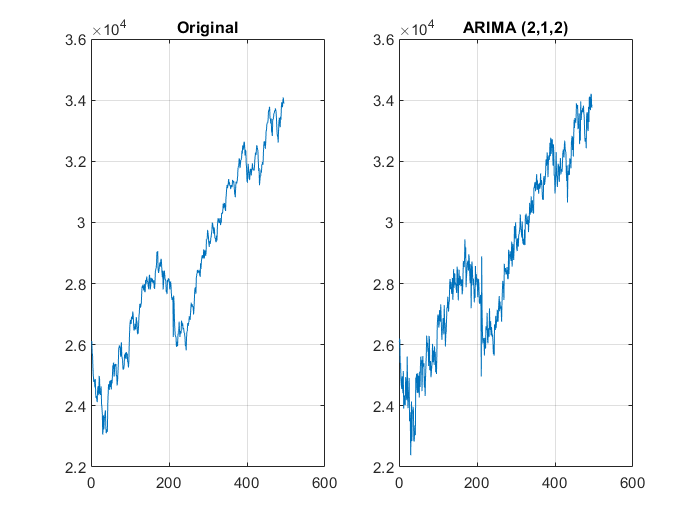


residual2= infer(ARIMA_Prac1, openingdata');        % Similar to the previous steps
prediction2= openingdata +residual2';

figure
subplot(1,2,1);
plot(openingdata);
title("Original");
grid on
subplot(1,2,2);
plot(prediction2);
title("ARIMA (2,1,2)");
grid on

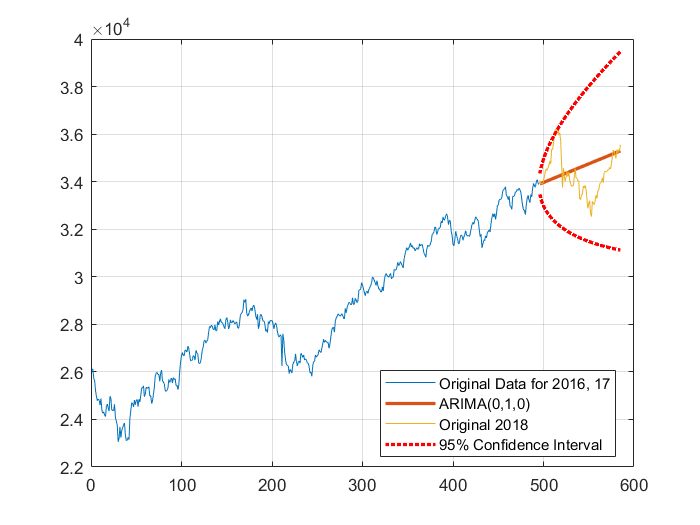


%FORECASTING THE FUTURE:
%IN THIS SECTION, WE WILL BE FORECASTING THE FUTURE DATA FOR THREE MONTHS AND
%COMPARE IT WITH THE ORIGINAL VALUES TO GET A BETTER UNDERSTANDING.

newlength=90;

% Now, let us plot the forecasted data for ARIMA(0,1,0) model along with a
% 95 percent confidence interval.

[Final_Theo_Forecast,ymse1]= forecast(ARIMA_Theo1, newlength,'Y0', openingdata');
lower_theo= Final_Theo_Forecast - 1.96*sqrt(ymse1);
upper_theo= Final_Theo_Forecast + 1.96*sqrt(ymse1);

figure
h1 = plot(fullopeningdata(1493:1987));
hold on
h2 = plot((496:495+newlength),Final_Theo_Forecast,'LineWidth',2);
h3 = plot((496:495+newlength),fullopeningdata(1988:2077));
h4 = plot((496:495+newlength),lower_theo,'r:','LineWidth',2);
h5 = plot((496:495+newlength),upper_theo,'r:','LineWidth',2);
legend([h1,h2,h3,h4],"Original Data for 2016, 17","ARIMA(0,1,0)","Original 2018","95% Confidence Interval","Location","Best");
grid on
hold off

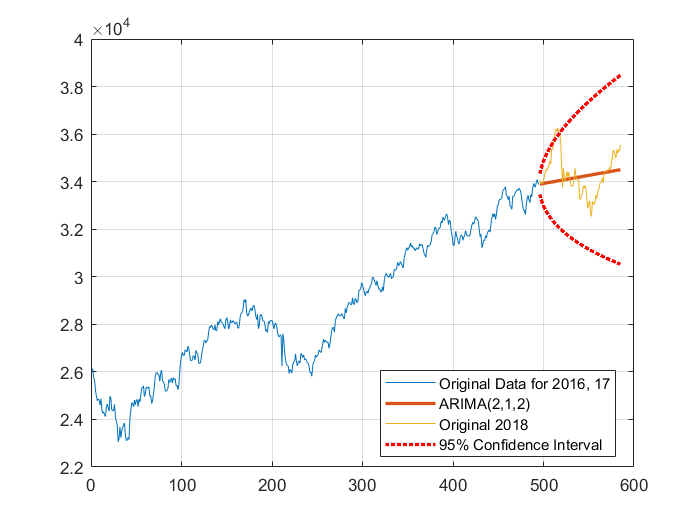


% Now, let us plot the forecasted data for ARIMA(2,1,2) model along with a
% 95 percent confidence interval.

[Final_Prac_Forecast,ymse2]= forecast(ARIMA_Prac1, newlength,'Y0', openingdata');
lower_prac= Final_Prac_Forecast - 1.96*sqrt(ymse2);
upper_prac= Final_Prac_Forecast + 1.96*sqrt(ymse2);

figure
h1 = plot(fullopeningdata(1493:1987));
hold on
h2 = plot((496:495+newlength),Final_Prac_Forecast,'LineWidth',2);
h3 = plot((496:495+newlength),fullopeningdata(1988:2077));
h4 = plot((496:495+newlength),lower_prac,'r:','LineWidth',2);
h5 = plot((496:495+newlength),upper_prac,'r:','LineWidth',2);
legend([h1,h2,h3,h4],"Original Data for 2016, 17","ARIMA(2,1,2)","Original 2018","95% Confidence Interval","Location","Best");
grid on
hold off

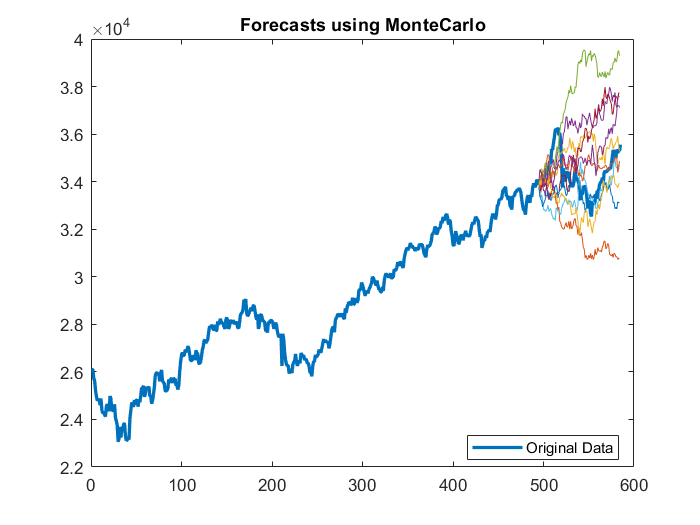



% FINAL PART: USING MONTE CARLO SIMULATION.
% The other possible curves can be analysed by using Monte Carlo simulation,
% which basically tells us the possible curves with which the data may
% takeoff based on the original and previously estimated values.

[MonteCarlo,~]=simulate(ARIMA_Theo1,newlength,'NumPath',10,'Y0',openingdata');

figure
h1 = plot(fullopeningdata(1493:1987+newlength),'LineWidth',2);
hold on
h2 = plot((n1:n1+newlength-1),MonteCarlo);
title("Forecasts using MonteCarlo");
legend(h1,"Original Data","Location","Best");